# 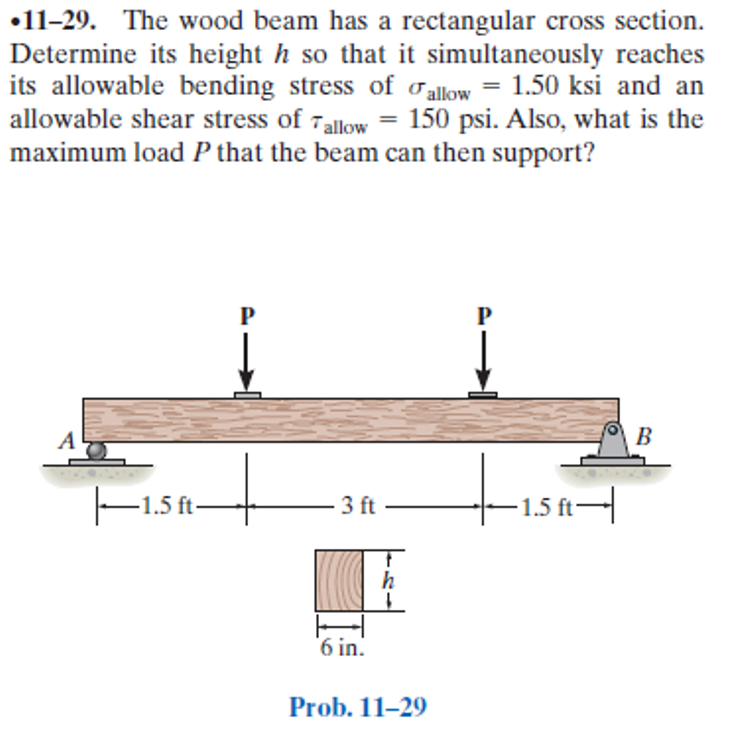

# assumptions

old_assum = assumptions;
clearassum;

# allowable stresses

u = symunit;
sigma_allow = 1.50*u.ksi;
tau_allow = 150*u.psi;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 6*u.ft);
b = b.add('applied', 'force', '-P', 1.5*u.ft);
b = b.add('applied', 'force', '-P', 4.5*u.ft);
b.L = 6*u.ft;

# section properties

B = 6*u.in;
H = sym('H', 'positive');
b.I(H) = rewrite(B*H^3/12, u.ft);

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} \frac{P\,x\,\left(2\,x-9\,\mathrm{ft}\right)\,\left(2\,x+9\,\mathrm{ft}\right)}{\text{E}\,H^{3}}\,\frac{1}{\mathrm{ft}} & \text{ if }x\leq \frac{3}{2}\,\mathrm{ft}\\ \frac{9\,P\,\left(4\,x^{2}-24\,x\,\mathrm{ft}+3\,{\mathrm{ft}}^{2}\right)}{2\,\text{E}\,H^{3}} & \text{ if }x\in \left(\frac{3}{2}\,\mathrm{ft},\frac{9}{2}\,\mathrm{ft}\right]\\ -\frac{P\,\left(x-6\,\mathrm{ft}\right)\,\left(2\,x-3\,\mathrm{ft}\right)\,\left(2\,x-21\,\mathrm{ft}\right)}{\text{E}\,H^{3}}\,\frac{1}{\mathrm{ft}} & \text{ if }\frac{9}{2}\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{3\,P\,\left(27\,{\mathrm{ft}}^{2}-4\,x^{2}\right)}{\text{E}\,H^{3}}\,\frac{1}{\mathrm{ft}} & \text{ if }x\leq \frac{3}{2}\,\mathrm{ft}\\ \frac{36\,P\,\left(x-3\,\mathrm{ft}\right)}{\text{E}\,H^{3}} & \text{ if }x\in \left(\frac{3}{2}\,\mathrm{ft},\frac{9}{2}\,\mathrm{ft}\right]\\ -\frac{3\,P\,\left(4\,x^{2}-48\,x\,\mathrm{ft}+117\,{\mathrm{ft}}^{2}\right)}{\text{E}\,H^{3}}\,\frac{1}{\mathrm{ft}} & \text{ if }\frac{9}{2}\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} P\,x & \text{ if }x\leq \frac{3}{2}\,\mathrm{ft}\\ \frac{3\,P}{2}\,\mathrm{ft} & \text{ if }x\in \left(\frac{3}{2}\,\mathrm{ft},\frac{9}{2}\,\mathrm{ft}\right]\\ -P\,\left(x-6\,\mathrm{ft}\right) & \text{ if }\frac{9}{2}\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} P & \text{ if }x\leq \frac{3}{2}\,\mathrm{ft}\\ 0 & \text{ if }x\in \left(\frac{3}{2}\,\mathrm{ft},\frac{9}{2}\,\mathrm{ft}\right]\\ -P & \text{ if }\frac{9}{2}\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = 0$$

addvar(y);

# reactions

Ra = r.Ra %#ok

$$Ra = P$$

Rb = r.Rb %#ok

$$Rb = P$$

clear Ra Rb;

# shear and moment diagram

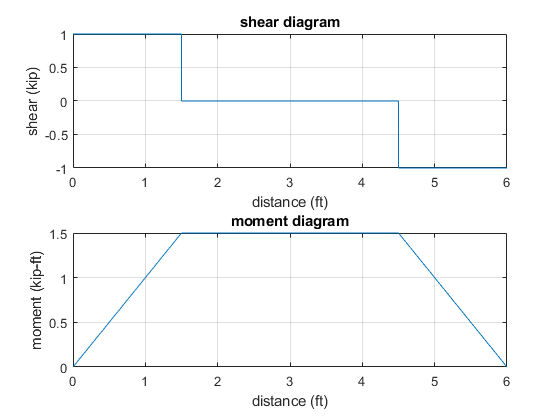

beam.shear_moment(m, v, [0 b.L], P, 1, {'kip' 'ft'});

# maximum bending moment

M_max(P) = m(1.5*u.ft);
C(H) = H/2;
b.I = rewrite(b.I, u.in);
sigma_max(P, H) = simplify(formula(M_max)*C/b.I)

$$sigma\_max(P, H) = \frac{18\,P}{H^{2}}$$

# maximum shear stress

V_max(P) = v(0);
A(H) = B*H;
tau_max(P, H) = simplify(1.5*formula(V_max)/A)

$$tau\_max(P, H) = \frac{P}{4\,H}\,\frac{1}{\mathrm{in}}$$

# maximum load P and mimum depth H

eqn = sym.zeros(2,1);
eqn(1) = sigma_max == sigma_allow;
eqn(2) = tau_max == tau_allow;
[P_max H_min] = solve(eqn, [P H]); %#ok
P_max = rewrite(P_max, u.kip);
H_min = rewrite(H_min, u.in);
P_max_vpa = vpa(P_max) %#ok

$$P\_max\_vpa = 4.32\,\mathrm{kip}$$

H_min_vpa = vpa(H_min) %#ok

$$H\_min\_vpa = 7.2\,\mathrm{in}$$

setassum(old_assum, 'clear');
clear P_max_vpa H_min_vpa old_assum;